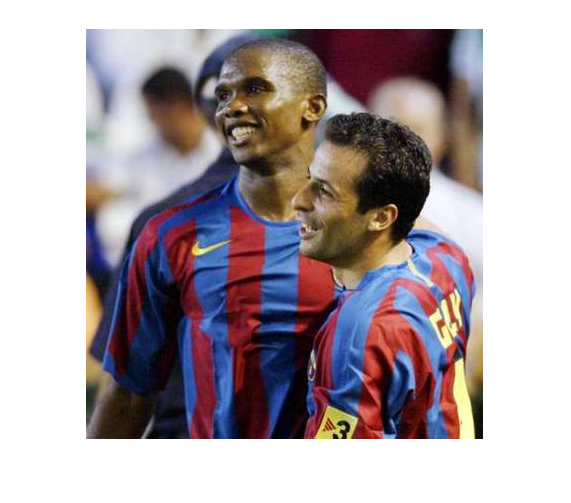

im = imread('soccer\barcelona\34.jpg');
im2 = imread('soccer\barcelona\35.jpg');

imshow(im);

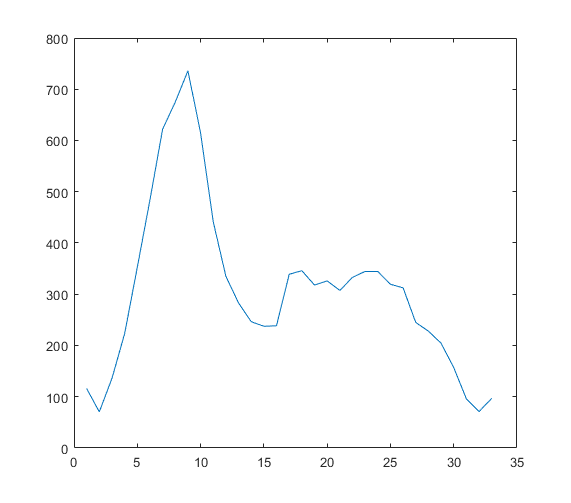

tam = 50;
[RGModelHist, GBModelHist, BRModelHist, RGBModelHist] = getHists(im, tam);
[RGModelHist2, GBModelHist2, BRModelHist2, RGBModelHist2] = getHists(im2, tam);

RGModelHist = (RGModelHist + RGModelHist2)/2;
plot(RGModelHist)

GBModelHist = (GBModelHist + GBModelHist2)/2;
BRModelHist = (BRModelHist + BRModelHist2)/2;
RGBModelHist = (RGBModelHist + RGBModelHist2)/2;

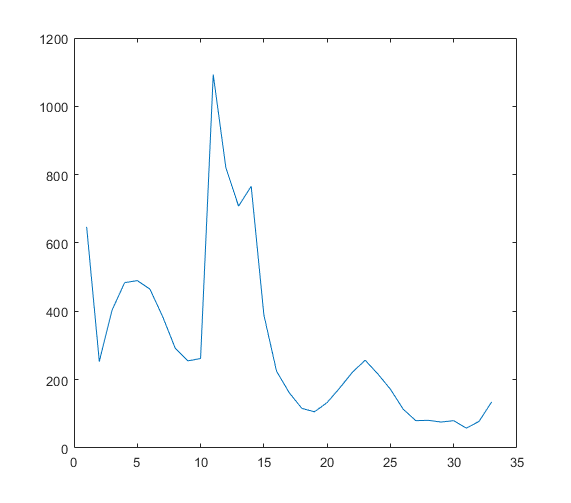

ans = 0

cercaEquip(RGModelHist, GBModelHist, BRModelHist, RGBModelHist, imread('soccer\barcelona\01.jpg')) 

function result = cercaEquip(RModelHist, RGModelHist, BModelHist, GBModelHist,im)
    
    [x, y] = size(im(:,:,1)); 
    r = im(:,:,1);
    g = im(:,:,2);
    b = im(:,:,3);
    
    I = (double(r) + double(g) + double(b))/3;
    red = double(r)./I;
    gre = double(g)./I;
    blu = double(b)./I;
    
    im = cat(4, red, gre, blu, blu);
    [c, f] = colCenter(im, 1, 3);
    
    result = false;
    tam = 50;
    fma = f+tam;
    fmi = f-tam;
    cmi = c-tam;
    cma = c+tam;
    if((f+tam)> x)
        fma = x;
        fmi = x-(tam*2);
        if(fmi < 1) 
            fmi = 1;
        end
    elseif((f-tam) < 1)
        fmi = 1;
        fma = 1+(tam*2);
        if(fma > x) 
            fma = x;
        end
    end
    
    if((c+tam)> y)
        cma = y;
        cmi = y-(tam*2);
        if(cmi < 1) 
            cmi = 1;
        end
    elseif((c-tam) < 1)
        cmi = 1;
        cma = 1+(tam*2);
        if(cma > y) 
            cma = y;
        end
    end
    
    
    im(:,:,2) = uint8(normalize(im(:,:,2).*im(:,:,1), 'range')*255); %RG
    im(:,:,1) = uint8(normalize(im(:,:,1), 'range')*255); %R
    im(:,:,3) = uint8(normalize(im(:,:,3), 'range')*255); %B
    im(:,:,4) = uint8(normalize(im(:,:,3).*im(:,:,2), 'range')*255); %GB
    
    RImgeHist = colorHistogram(fmi, fma, cmi, cma, 1, im);
    plot(RImgeHist)
    RGImgeHist = colorHistogram(fmi, fma, cmi, cma, 2, im);
    BImgeHist = colorHistogram(fmi, fma, cmi, cma, 3, im);
    GBImgeHist = colorHistogram(fmi, fma, cmi, cma, 4, im);
            
    errR = distChiSq(RImgeHist, RModelHist);
    errRG = distChiSq(RGImgeHist, RGModelHist);
    errB = distChiSq(BImgeHist, BModelHist);
    errGB = distChiSq(GBImgeHist, GBModelHist);
    
    %errR
    %errRG
    %errB
    %rrGB
    
    res = 0;
    
    if (errR < 850 || errB < 850)
        res = res + 1;
    end
    
    if (errGB > 2000)
        res = res - 2;
    end
    
    if (errR > 2000)
        res = res - 2;
    end
    
    if ((errR + errB) < 2000)
        res = res + 2;
    else 
        res = res - 2;
    end
    
    if (errRG < 1200)
        res = res + 1;
    end
    
    if (errGB < 1200)
        res = res + 1;
    end
    
    res;
    
    if (res > 0)
        result = 1;
    else
        result = 0;
    end
    
end

function [c, f] = centerr(im, d)

    [x,y] = size(im(:,:,1));
    res = zeros(1,y);
    max = 0;
    for i = [1:y]
        res(1, i) = nansum(im(:,i,d));
        if (res(1,i) > max)
            c = i;
            max = res(1, i);
        end
    end
    max = 0;
    res = zeros(1,x);
    for i = [1:x]
        res(1, i) = nansum(im(i,:,d));
        if (res(1,i) > max)
            f = i;
            max = res(1, i);
        end
    end
end

function [c, f] = colCenter(im, d1, d2)

    [c, f] = centerr(im, d1);
    [cc, ff] = centerr(im, d2);
    
    c = uint16((cc+c)/2);
    f = uint16((ff+f)/2);

end

function [rHist, gHist, bHist, oHist] = getHists(im, tam)

    r = im(:,:,1);
    g = im(:,:,2);
    b = im(:,:,3);
    
    I = (double(r) + double(g) + double(b))/3;
    red = double(r)./I;
    gre = double(g)./I;
    blu = double(b)./I;
    
    im = cat(4, red, gre, blu, blu);
    
    [c, f] = colCenter(im, 1, 3);
    %tam = 75;
    
    im(:,:,4) = uint8(normalize(im(:,:,3).*im(:,:,2), 'range')*255); 
    im(:,:,2) = uint8(normalize(im(:,:,2).*im(:,:,1), 'range')*255); 
    im(:,:,1) = uint8(normalize(im(:,:,1), 'range')*255);
    im(:,:,3) = uint8(normalize(im(:,:,3), 'range')*255);
    
    
    rHist = colorHistogram(f-tam, f+tam, c-tam, c+tam, 1, im);
    gHist = colorHistogram(f-tam, f+tam, c-tam, c+tam, 2, im);
    bHist = colorHistogram(f-tam, f+tam, c-tam, c+tam, 3, im);
    oHist = colorHistogram(f-tam, f+tam, c-tam, c+tam, 4, im);

end

function model = colorHistogram(xini, xfin, yini, yfin, color, im)
    model = zeros(1, 33);
    for i = [yini:yfin]
        for j = [xini:xfin]
            model(1, uint8(im(j, i, color)/8)+1) = model(1, uint8(im(j, i, color)/8)+1) + 1;
        end
    end
    %bar(model);
end

function D = distChiSq( X, Y )

    m = size(X,1);  
    n = size(Y,1);
    mOnes = ones(1,m); 
    D = zeros(m,n);
    
    for i=1:n
      yi = Y(i,:);  
      yiRep = yi( mOnes, : );
      s = yiRep + X;    
      d = yiRep - X;
      D(:,i) = sum( d.^2 ./ (s+eps), 2 );
    end
    D = D/2;
end